clear
clc
close all

## Data

Let's first load the soundfile and listen to the file.

[x, fs] = audioread('sa1.wav'); % read the audio file; fs = 16000
sound(x, fs)                    % play the audio file

It would read as "She had your dark suit in grease all year".

Now, we configure some parameters.

fr_len = 40;                    % 40 ms frame (1 ms = 0.001 sec)

fr_N = ((fr_len/1000)*fs);      % divide by 1000 to convert to second (0.040 sec * 16000 fs)
shift_R = fr_N/5;               % shift ratio is 1/5 of the frame size
w = window(@hamming,fr_N);      % create a hamming window

If warning <undefined function 'window' for input arguments of type 'function_handle'.> occur, download add-on "Signal Processing Toolbox" from APPS.

## Spectrogram

This will plot the spectrogram of the audiofile.

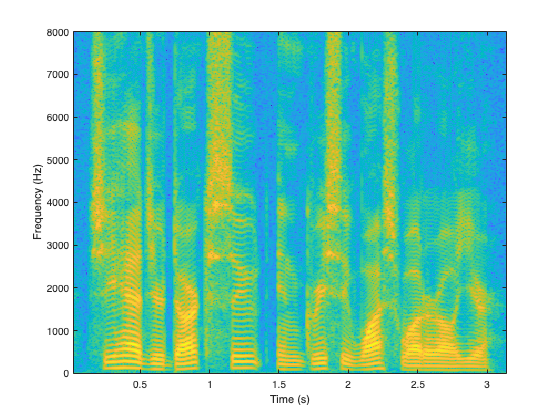

[S,F,T,P] = spectrogram(x,w,(fr_N-shift_R),fr_N,fs); % syntax: [s,f,t,ps] = spectrogram(x,window,noverlap,f,fs)
figure                          % create a figure
imagesc(T,F,20*log10(abs(S)));  % display the image with scaled color on the figure
axis xy
xlabel('Time (s)')
ylabel('Frequency (Hz)');

Here are what spectrogram() function returns:

- S: short-time Fourier transform of the input signal, `x`. Each column of `s` contains an estimate of the short-term, time-localized frequency content of `x`.

- F: a vector of cyclical frequencies, [`f`](https://www.mathworks.com/help/signal/ref/spectrogram.html#bultmx7-f-dup1), expressed in terms of the sample rate, `fs`. `fs` must be the fifth input to `spectrogram`. To input a sample rate and still use the default values of the preceding optional arguments, specify these arguments as empty, `[]`.

- T: a vector of time instants, [`t`](https://www.mathworks.com/help/signal/ref/spectrogram.html#bultmx7-t), at which the spectrogram is computed.

- P: a matrix, `ps`, containing an estimate of the power spectral density (PSD) or the power spectrum of each segment.

## Fixed time or frequency

(1) For a fixed time value (m), this represents the Fourier transform of the windowed signal.

m = 0.435                           % pick a time, for this example, m = 0.435 sec

m = 0.4350

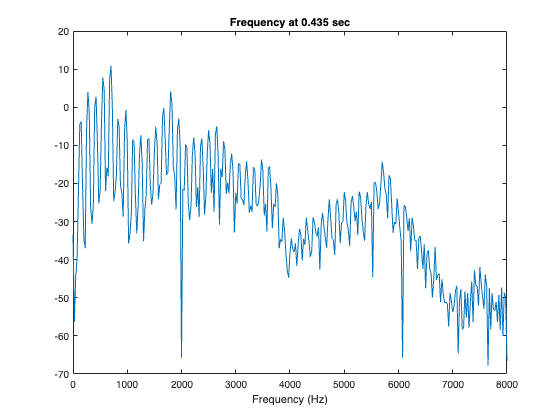


figure                              % create another figure
[temp1, temp2] = min(abs(T-m));     % at a fixed time, m
plot(F, 20*log10(abs(S(:,temp2)))); % plot against frequency
title(['Frequency at ', num2str(m), ' sec'])
xlabel('Frequency (Hz)');

(2) For a fixed frequency, we get a sense of how the amplitude of this component changes over time.

fixed_f = 540                           % pick a frequency, for this example, 540 Hz

fixed_f = 540

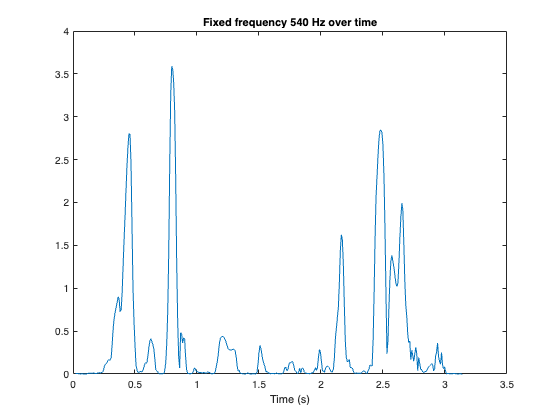


figure                                  % create another figure
[temp1, temp2] = min(abs(F-fixed_f));   % at a fixed frequency
plot(T, (abs(S(temp2,:))));             % plot against time
title(['Fixed frequency ', num2str(fixed_f), ' Hz over time'])
xlabel('Time (s)');